## Simulating and testing stuff

This script shows examples for super simple simulations and what you can do with them. we some recapping and application of the new concepts to basic wavelt morlets. 

clear all
edit wavelet_app_mat.m
edit gener_wav.m  % change m and see what happens when you do it again...
% here you can change the m parameter; setting a lower m will give more
% resolution in higher frequencies. 

Measure the time and frequency resolution with an impulse response. This is an alternative to calculating the time and frequency resolution as discussed last time. 

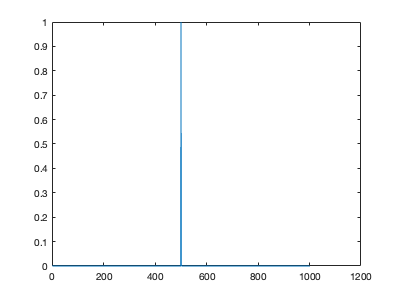


pulse = zeros(1,1001); % if sampled at 500 Hz, these 1001 points are 2.002 sec :-) 

pulse(501)=1;

figure, plot(pulse)

Now we have the pulse; looks fairly useless, but let's see. If you feel bored, call it Dirac Pulse. 

[https://en.wikipedia.org/wiki/Paul_Dirac](https://en.wikipedia.org/wiki/Paul_Dirac)

 "His colleagues in Cambridge jokingly defined a unit called a "dirac", which was one word per hour."

Now a wavelet analysis of the pulse signal. We need a time axis and a frequency axis, which will start with ALL possible frequencies. Then we pick a subset of frquencies to be calculated, for economy. you coudl easily just run all of them too. try it out! 

timeaxis = 0:2:2000; % in miliseconds, could use seconds too

freqstep = 1000/2002; % the best possible frequency resolution we can 
% have with a segment of this length

freqs_all = 0:freqstep:250; % can start at 0 Hz, up to half the sample rate (Nyquist)

freqs_wanted = freqs_all(7:2:61); % here we pick a subset

OK now we run the wavelet code with the settings as determined above. before we do, we should calcuate the sigmaT and sigmaF analytically. 

in our example: sigmaf = freqofinterest/m

if we are interested in 10 Hz, and using m=10, then sigmaf = 10/10 = 1 :-) 

therefore sigmaT = 1./(2*pi*sigmaf) = 0.1592 seconds (it's in seconds because we used Hz [cycles per sec] as the unit)

[WaPowerP] = wavelet_app_mat(pulse, 500, 7, 61, 2);

size of waveletMatrix
          28        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.


figure, contourf(timeaxis, freqs_wanted, squeeze(WaPowerP(1, :, :))', 20), colorbar

## Now we determine the full width at half maximum (FWHM) empirically, at 10 Hz, or any other frequency we care about. 

freqs_wanted(8) % to find 10 Hz 

ans = 9.9900

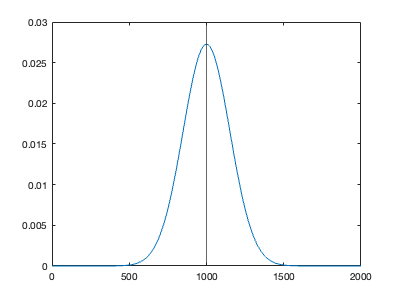

% plot only the 10 Hz wavelet's result
figure
plot(timeaxis, WaPowerP(1, :, 8)), xline(1000)
hold on

find the maximum, and the half maximum

[maxval, index]=max(WaPowerP(1, :, 8))

maxval = 0.0273

index = 501


%half maximum: 
halfmax = maxval./2

halfmax = 0.0136

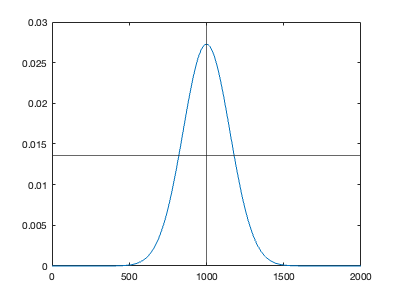

%plot(timeaxis, WaPowerP(1, :, 8)), 
yline(halfmax) 
hold on

find the x-coordinate where the signal reaches half maximum, need only one side of the signal, as it is symmetrical

timeindex = find(WaPowerP(1, 1:501, 8)<halfmax)

timeindex =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


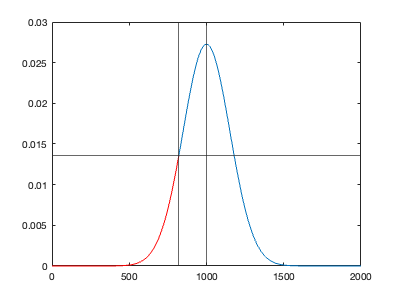

plot(timeaxis(timeindex), WaPowerP(1, timeindex, 8), 'r')
xline(timeaxis(max(timeindex)))

now we can eaisly find the temporal distance fro the maximum at 1000 ms (the middle) to the half maximum point to the left. Then we multipy by 2 to get the FULL width at half maximum (FWHM)

almostthere = 1000-timeaxis(max(timeindex))

almostthere = 180

FWHM = 2* almostthere

FWHM = 360

% in seconds
FWHM = FWHM/1000

FWHM = 0.3600

OK where does that leave us!? it seems the FWM is about twice as large as the sigmaT.. is one of them wrong ? No

[https://brainder.org/2011/08/20/gaussian-kernels-convert-fwhm-to-sigma/](https://brainder.org/2011/08/20/gaussian-kernels-convert-fwhm-to-sigma/)

in our case: 

sigmaT = 0.1592

sigmaT = 0.1592

disp('predicted FWHM:')

predicted FWHM:


FWHMsigma = 2.355 * sigmaT

FWHMsigma = 0.3749

%the diference: 
differenceFWHMs = FWHM - FWHMsigma

differenceFWHMs = -0.0149

## Simulating and testing oscillations

let's pick up the pace. let's make a bunch of signals for testing the accurate representation of waveforms in wavelet analaysis. note that you can use thse signals including the pulse above on ANY method. 

the simplest case: a sine and cosine wave at 20 Hz ( just for variety, let's do another frequency) 

timeaxis = 0:0.002:2; % in seconds for easier conversion to Hz
sine_20 = sin(2*pi*timeaxis*20); 
cosine_20 = cos(2*pi*timeaxis*20); 
saw_20 = sawtooth(2*pi*timeaxis*20); 
figure
plot(timeaxis(1:100), sine_20(1:100)), hold on
plot(timeaxis(1:100), cosine_20(1:100), 'r'), hold on
plot(timeaxis(1:100), saw_20(1:100), 'g'), hold on

submit to wavelet analysis

[WaPowerSine] = wavelet_app_mat(sine_20, 500, 7, 61, 2);

size of waveletMatrix
          28        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.

[WaPowerCosine] = wavelet_app_mat(cosine_20, 500, 7, 61, 2);

size of waveletMatrix
          28        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.

plot the results

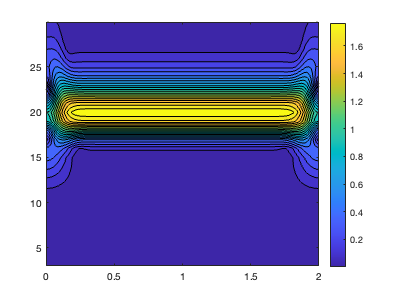

figure, contourf(timeaxis, freqs_wanted, squeeze(WaPowerSine(1, :, :))', 20), colorbar

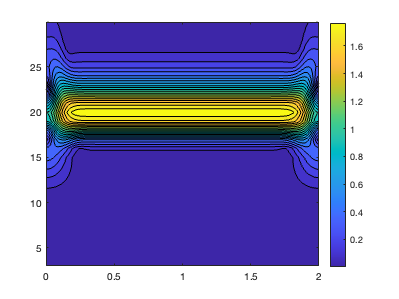

figure, contourf(timeaxis, freqs_wanted, squeeze(WaPowerCosine(1, :, :))', 20), colorbar

pay attention to the smearing in the frequency domain - we could use this to estimate the FWHM in the frequency domain, and compare with sigmaF

pay attention to the magnitude on the colorbar. would we expect 1.6 ??? what would we expect ? 

these signals are super unrealistic. Often, we want something like EEG in which the tesyt signal is embedded. There are multiple ways to do this. 

start with white noise of the same size

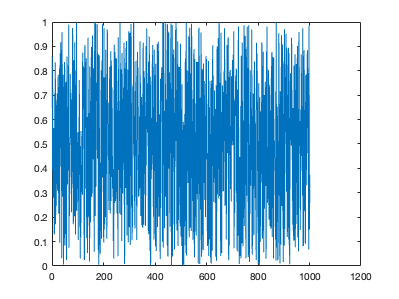

stochasticsig = rand(size(sine_20)); 
figure
plot(stochasticsig) % this will look different every time :-) 

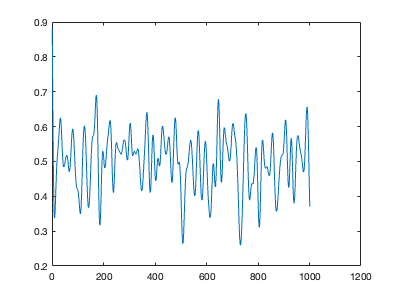

% not very EEG-like, let's get it filtered
[a,b] = butter(4, 0.1); % filters at 25 Hz lp why why oh why ? (hint 0.1 times nyquist with fsamp = 500Hz)
stochasticsig_filt = filtfilt(a,b,stochasticsig); 
figure
plot(stochasticsig_filt), hold on

this filter creates on and offset artifacts, need a window, 

maybe a hanning window? this is one of the most widely used  standard windows used in signal  processing. 

plot(hanning(1001))
stochasticsig_filt = filtfilt(a,b,stochasticsig'.*hanning(1001)); 
plot(stochasticsig_filt)

 hm! this is not as intended ! this is why windows are applied in the time domain, on the input data, not on the output

stochasticsig = bslcorr(stochasticsig, 1:100);
stochasticsig_filt_h = filtfilt(a,b,stochasticsig'.*hanning(1001)); 
plot(stochasticsig_filt_h, 'k'),

this window is still a bit weird in that it only weights ONE point in the middle with zero and suppresses all other points. That can't be good, right ? alternatively, can use a window with a short ramp on and ramp off period. 

figure
coswin = cosinwin(40, 1001);
plot(coswin, 'm'), hold on
stochasticsig_filt_c = filtfilt(a,b,stochasticsig.*coswin); 
plot(stochasticsig_filt_h, 'k'),
plot(stochasticsig_filt_c, 'r'),

alternatively, we can just use a brownian noise generator 

brownnoise = spatialPattern([1,1001],-2); 
figure
plot(brownnoise, 'k'), hold on
brownnoise_w = brownnoise .* coswin; 
plot(brownnoise_w, 'r'), yline(0)

Ok now that we have realistic workable EEG for any given trial, we may add our oscillation to it. To make it more finformative, we normalize it to 1 (like the sine) embed it only into the middle part of the signal

testsig_orig = stochasticsig_filt_c./max(stochasticsig_filt_c);
testsig = testsig_orig; 
testsig(250:750) = testsig_orig(250:750) + sine_20(250:750); 
figure
plot(testsig, 'b')

not optimal! need ongoing "EEG" to be still larger and signal still smaller, to look realistic In fact, in many simulations, you would want to manipulate this systematically, to analyze the effect of SNR on your analysis. 

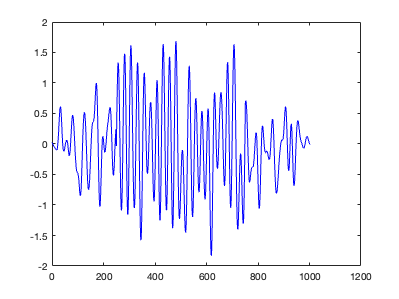

testsig = testsig_orig; 
for signalgain = 0.01:0.03:1.2
    testsig(250:750) = testsig_orig(250:750) + signalgain.*sine_20(250:750); 
    plot(testsig, 'b'), pause(.2)
end

now apply this for example to the wavelet analysis

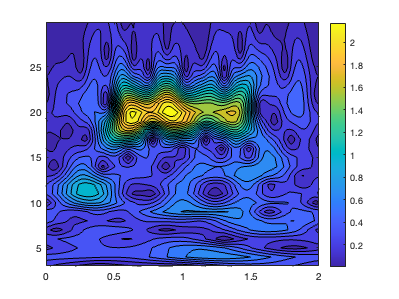

size of waveletMatrix
          28        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.size of waveletMatrix
          28        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.size of waveletMatrix
          28        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.size of waveletMatrix
          28        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.size of waveletMatrix
          28        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.size of waveletMatrix
          28        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.size of waveletMatrix
          28        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.size of waveletMatrix
          28        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.size of waveletMatrix
  

figure
testsig = testsig_orig; 
for signalgain = 0.01:0.03:1.2
    testsig(250:750) = testsig_orig(250:750) + signalgain.*sine_20(250:750); 
    [WaPowertestsig] = wavelet_app_mat(testsig, 500, 7, 61, 2);
    contourf(timeaxis, freqs_wanted, squeeze(WaPowertestsig(1, :, :))', 20), colorbar, pause(.2)
end

Let's check for Harmonics

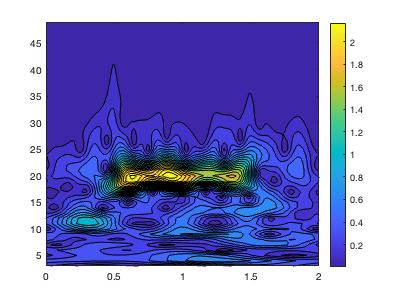

size of waveletMatrix
          47        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.size of waveletMatrix
          47        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.size of waveletMatrix
          47        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.size of waveletMatrix
          47        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.size of waveletMatrix
          47        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.size of waveletMatrix
          47        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.size of waveletMatrix
          47        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.size of waveletMatrix
          47        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.size of waveletMatrix
  

figure
testsig = testsig_orig; 
for signalgain = 0.01:0.03:1.2
    testsig(250:750) = testsig_orig(250:750) + signalgain.*sine_20(250:750); 
    [WaPowertestsig] = wavelet_app_mat(testsig, 500, 7, 100, 2);
    contourf(timeaxis, freqs_all(7:2:100), squeeze(WaPowertestsig(1, :, :))', 20), colorbar, pause(.2)
end

and I have not forgotten about the sawtooth

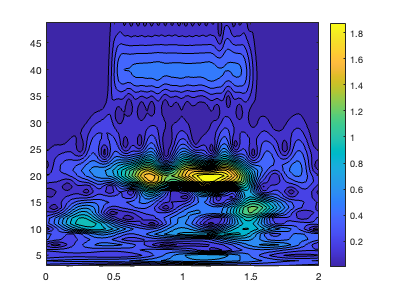

size of waveletMatrix
          47        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.size of waveletMatrix
          47        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.

size of waveletMatrix
          47        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.size of waveletMatrix
          47        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.size of waveletMatrix
          47        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.size of waveletMatrix
          47        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.size of waveletMatrix
          47        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.size of waveletMatrix
          47        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.size of waveletMatrix
          47        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.size of waveletMatrix
          47        1001

 frequency step for delta_f0 = 1 is 
    0.4995

trial index of 
     1

.size of waveletMatrix
  

figure
testsig = testsig_orig; 
for signalgain = 0.01:0.03:1.2
    testsig(250:750) = testsig_orig(250:750) + signalgain.*saw_20(250:750); 
    [WaPowertestsaw] = wavelet_app_mat(testsig, 500, 7, 100, 2);
    contourf(timeaxis, freqs_all(7:2:100), squeeze(WaPowertestsaw(1, :, :))', 20), colorbar, pause(.2)
end

thanks for watching! 